# MSc Project IIS1 | BWFLnet_Water Analysis

#### Prepared by: Yuanfei Wang

#### Date: 17 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_MSc_2022_calibrated';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_MSc_2022_calibrated.inp"...
Input File "BWFLnet_MSc_2022_calibrated.inp" loaded sucessfuly.


load("wq_data.mat");
load("R_CData.mat");

### Network Data Loading

Load general network data, noting that this network has already been hydraulically calibrated, thus we can directly perform the quality analysis.

% Save element count variables
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';
R = net.getLinkRoughnessCoeff';

% Save node and link index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;
Link_Idx = double(net.getLinkIndex);

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
days = 7; % simulation duration in days
net.setTimeSimulationDuration(nt*3600*days/7); % Set the simulation duration by changing days
nt = net.getTimeSimulationDuration./3600; % get the new nt

% Nodes name and chlorine concentrations
Junction_All_Name = {'BW9','BW7','BW1','BW2','BW3','BW4','BW5','BW6','BW12'};
Junction_SelectIdx = net.getNodeIndex(wq_data.node_ids([1,4,7,9]));
Junction_Name = Junction_All_Name([1,4,7,9]);
Junction_HydrantIdx = net.getNodeIndex(wq_data.node_ids([2,5,8]));
Junction_Hydrant_Name = Junction_All_Name([2,5,8]);
Junction_Reservoir_Name = Junction_All_Name([6,3]);
cext = wq_data.chlorine([6,3],:);
c_nodes_HydrantObs = wq_data.chlorine([2,5,8],:);
c_nodes_Obs = wq_data.chlorine([1,4,7,9],:);


### Graph Creation Preparation

Use graph theory to plot network connectivity and spatial coordinates.

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);


### Graph Plotting

Setup general chemical simulation parameters.

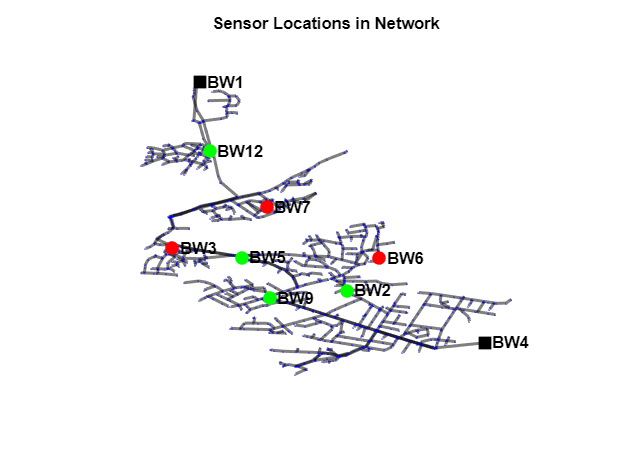

% Plot the sensor location on the network map
figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 2;
p1.EdgeColor = 'k';
p1.MarkerSize = 0.01;
p1.NodeColor = 'b';
p1.NodeLabel = '';
highlight(p1,Junction_SelectIdx,'NodeColor','green','MarkerSize',8);
labelnode(p1,Junction_SelectIdx,Junction_Name);
highlight(p1,Junction_HydrantIdx,'NodeColor','red','MarkerSize',8);
labelnode(p1,Junction_HydrantIdx,Junction_Hydrant_Name);
highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
labelnode(p1,Reservoir_Idx,Junction_Reservoir_Name);
p1.NodeFontSize = 11;
p1.NodeLabelColor = 'k';
p1.NodeFontWeight = 'bold';
p1.EdgeFontSize = 11;
p1.EdgeLabelColor = 'k';
p1.EdgeFontWeight = 'bold';
% p1.EdgeCData = R_CData;
% hcb_R = colorbar;
% colormap('jet');
% hcb_R.Label.String = 'Pipe Roughness Group';
% hcb_R.Label.FontSize = 12;
axis('off')
title('Sensor Locations in Network')

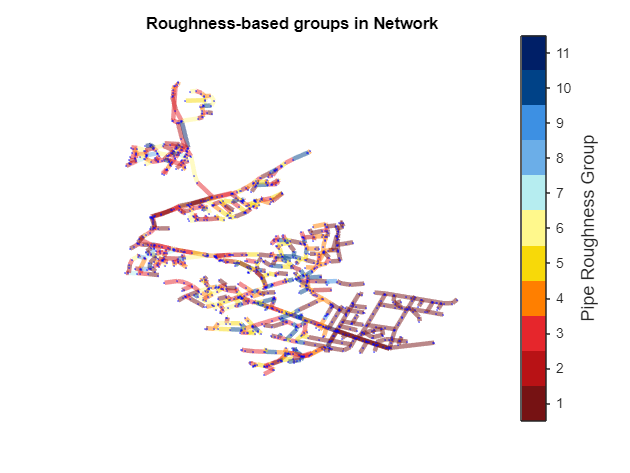

% Plot the Roughness group on the network map
figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 3;
p1.EdgeColor = 'k';
p1.MarkerSize = 1e-10;

p1.NodeColor = 'b';
p1.NodeLabel = '';
p1.NodeFontSize = 11;
p1.NodeLabelColor = 'k';
p1.NodeFontWeight = 'bold';
p1.EdgeFontSize = 11;
p1.EdgeLabelColor = 'k';
p1.EdgeFontWeight = 'bold';
p1.EdgeCData = R_CData;
cmap=[118 18 19; 
     184 18 21; 
     230 38 44; 
     255 127 0; 
     247 217 9; 
     255 248 140; 
     182 237 240; 
     107 174 232; 
     61 144 227; 
     0 66 135; 
     0 31 103];
cmap=cmap/255; 
colormap(cmap);
hcb = colorbar;
hcb.TicksMode = 'manual';
set(hcb,'Tickdir','out');
caxis([1,11]);
set(hcb,'YTick',1+5/11:10/11:11-5/11);
set(hcb,'TickLabels',{'1','2','3','4','5','6','7','8','9','10','11'});
hcb.Label.String = 'Pipe Roughness Group';
hcb.Label.FontSize = 12;
axis('off')
title('Roughness-based groups in Network')

### Chlorine Simulation

Setup general chemical simulation parameters.

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% % Link bulk reaction coefficients
% lambda = 0.5*ones(np,1); % units of days^-1
% net.setLinkBulkReactionCoeff(1:np, -lambda);
% net.setOptionsPipeBulkReactionOrder(1);

% Initial concentrations at nodes (mg/L)
c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);
base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 

% For loop to assign new patterns to source contrations at reservoirs and
% source type
for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end

### Results from EPANET Simulation

Simulate hydraulic and quality analyses using EPANET's solvers.

hydraulic_res = net.getComputedHydraulicTimeSeries;
quality_res = net.getComputedQualityTimeSeries;

% Assign hydraulic results to network elements
h = hydraulic_res.Head(1:1+4*nt,1:nn).';
q = 1e-3*hydraulic_res.Flow(1:1+4*nt,:).';

% Assign quality results to network elements
c_nodes = quality_res.NodeQuality';
c_pipes = quality_res.LinkQuality';

% Get the simulated and observed data
c_nodes_Sim = c_nodes(Junction_SelectIdx,:);
c_nodes_Sim = c_nodes_Sim(:,1:end-1);
c_nodes_HydrantSim = c_nodes(Junction_HydrantIdx,:);
c_nodes_HydrantSim = c_nodes_HydrantSim(:,1:end-1);
c_nodes_Reservoir = pattern_cext;

% split the data
Sim_train = c_nodes_Sim(:,2*96+1:3*96);
Sim_val = c_nodes_Sim(:,3*96+1:end);
Obs_train = c_nodes_Obs(:,2*96+1:3*96);
Obs_val = c_nodes_Obs(:,3*96+1:end);
mse_function = @(sim,obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));
mse_before_train = mse_function(Sim_train,Obs_train);
mse_before = mse_function(Sim_val,Obs_val);

### GA calibration

Assign an uniform bulk decay coefficient to the whole network based on literatures.

%  bulk reaction coefficient
lambda = 1.0*ones(np,1); % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda);
net.setOptionsPipeBulkReactionOrder(1); 

### Single wall decay coefficient GA calibration

Start the GA process with one single wall decay coefficient, regardless of the pipe roughness and diameter.

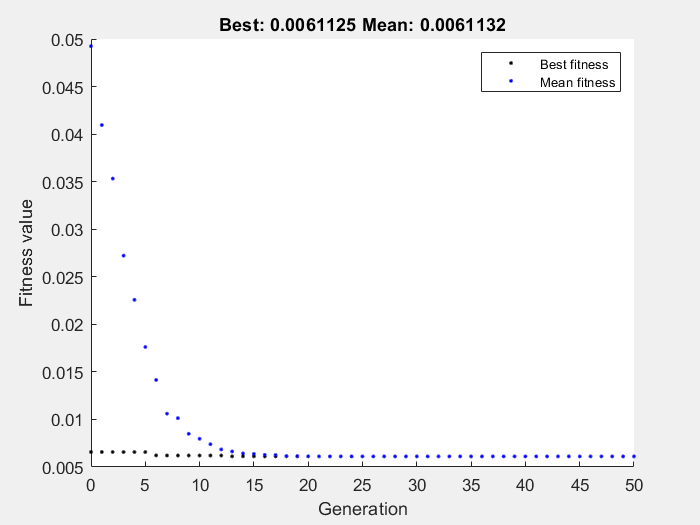

% Consider the whole network together and assign the same decay parameter

rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50,'InitialPopulation',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = -10;
ub = 0;

tic;
Mse_function = @(x) Mse_NoGroup(x,Obs_train,Junction_SelectIdx);
[x_NoGroup, fval_NoGroup] = ga(Mse_function,1,[],[],[],[],lb,ub,[],options);

t_NoGroup = toc;
fprintf('The computation time is %.2fs',t_NoGroup);

The computation time is 692.49s

% Test the ga result
theta_NoGroup = ones(2281,1); % units of m/day
for i = 1:2281
    theta_NoGroup(i) = x_NoGroup(1);
end
net.setLinkWallReactionCoeff(1:np, theta_NoGroup);
net.setOptionsPipeWallReactionOrder(1);
quality_res_NoGroup = net.getComputedQualityTimeSeries;

c_nodes_NoGroup = quality_res_NoGroup.NodeQuality';
c_nodes_Sim_NoGroup = c_nodes_NoGroup(Junction_SelectIdx,1:end-1);
c_nodes_Sim_Hydrant_NoGroup = c_nodes_NoGroup(Junction_HydrantIdx,1:end-1);
Sim_NoGroup_val = c_nodes_Sim_NoGroup(:,3*96+1:end);
mse_after_NoGroup = mse_function(Sim_NoGroup_val,Obs_val);
fprintf('The train mse before calibration is %.4f, after calibration it is %.4f',mse_before_train,fval_NoGroup);

The train mse before calibration is 0.0430, after calibration it is 0.0061

fprintf('The validation mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_NoGroup);

The validation mse before calibration is 0.0396, after calibration it is 0.0110

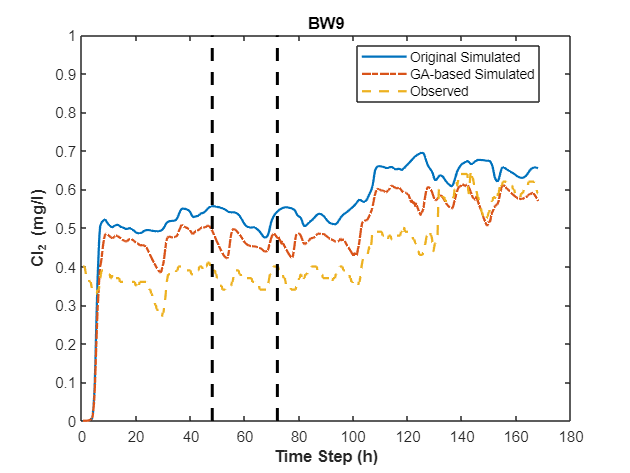

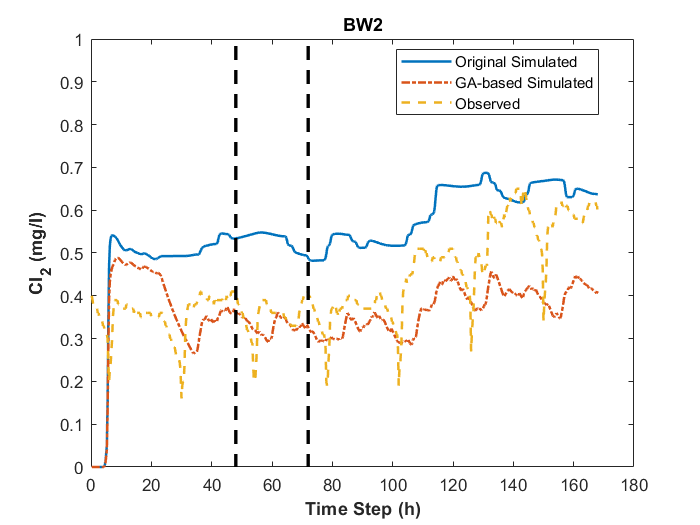

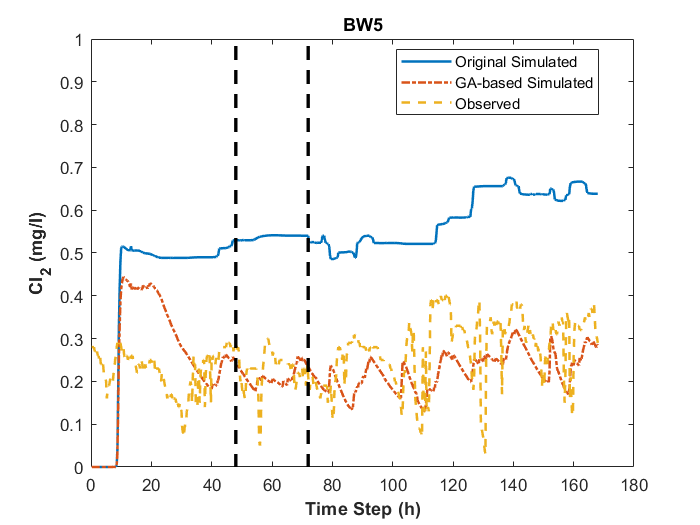

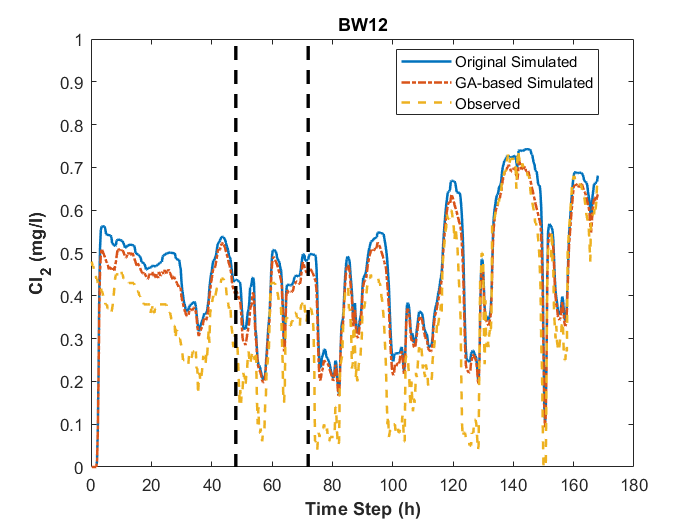


% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_NoGroup(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end

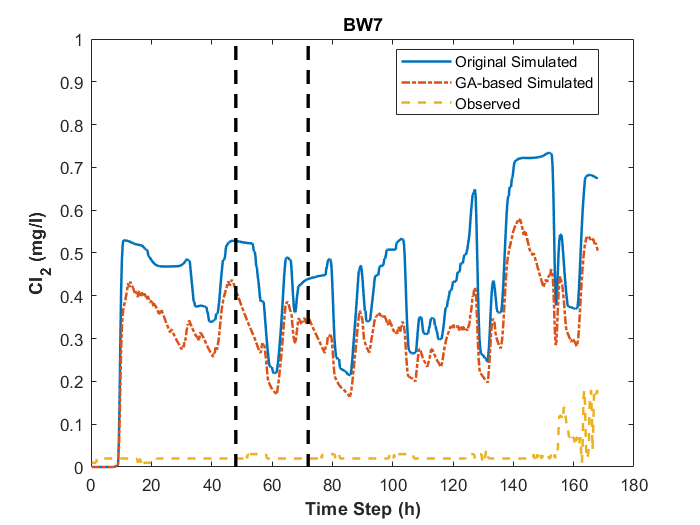

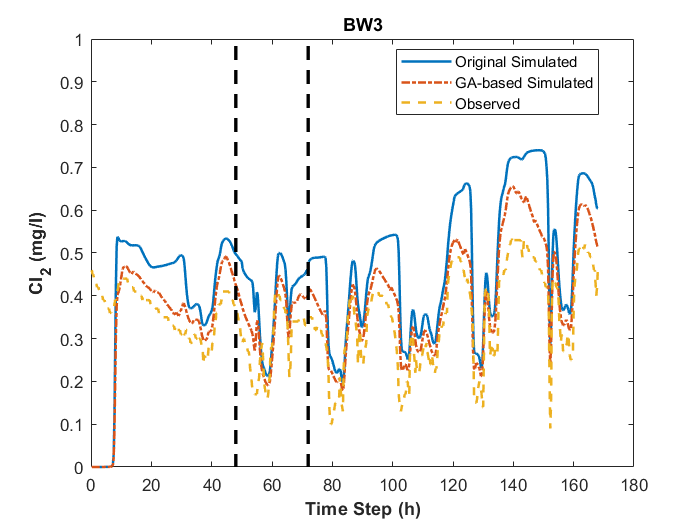

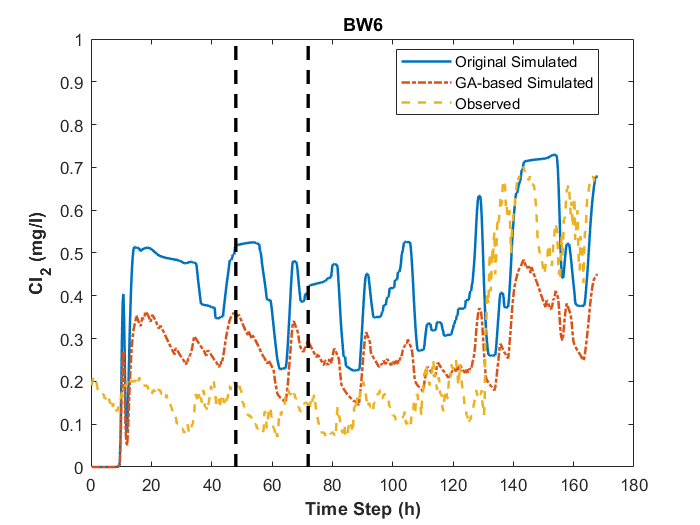

% figures for simulated and observed data (Hydrants)
for i = 1:size(c_nodes_HydrantObs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_HydrantSim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_Hydrant_NoGroup(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_HydrantObs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Hydrant_Name{i})
end

### Diameter based Group Genetic Algorithm Implementation

Implement genetic algoritnm to solve the parameter optimization problem based on diameter groups.

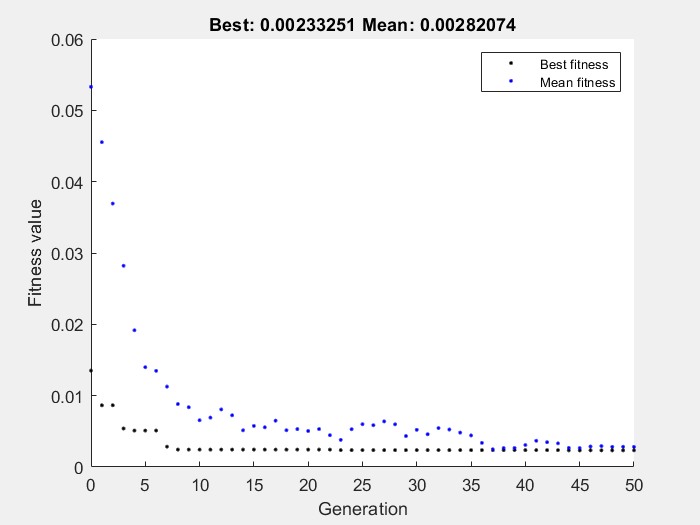

% % genetic algorithm implementation
rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = [-10,-10,-10,-10];
ub = [0,0,0,0];

tic;
Mse_function = @(x) Mse_D(x,Obs_train,Junction_SelectIdx,D);
[x_D, fval_D] = ga(Mse_function,4,[],[],[],[],lb,ub,[],options);


t_D = toc;
fprintf('The computation time is %.2fs',t_D);

The computation time is 597.49s


% Test the ga result
theta_D = ones(2281,1); % units of m/day
for i = 1:2281
    if D(i) <= 75
        theta_D(i) = x_D(1);
    elseif D(i) > 75 && D(i) <= 150
        theta_D(i) = x_D(2);
    elseif D(i) > 150 && D(i) <= 250
        theta_D(i) = x_D(3);
    else
        theta_D(i) = x_D(4);
    end
end
net.setLinkWallReactionCoeff(1:np, theta_D);
net.setOptionsPipeWallReactionOrder(1);
quality_res_D = net.getComputedQualityTimeSeries;
c_nodes_D = quality_res_D.NodeQuality';
c_nodes_Sim_D = c_nodes_D(Junction_SelectIdx,1:end-1);
c_nodes_Sim_Hydrant_D = c_nodes_D(Junction_HydrantIdx,1:end-1);

Sim_D_val = c_nodes_Sim_D(:,3*96+1:end);
mse_after_D = mse_function(Sim_D_val,Obs_val);
fprintf('The train mse before calibration is %.4f, after calibration it is %.4f',mse_before_train,fval_D);

The train mse before calibration is 0.0430, after calibration it is 0.0023

fprintf('The validation mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_D);

The validation mse before calibration is 0.0396, after calibration it is 0.0105

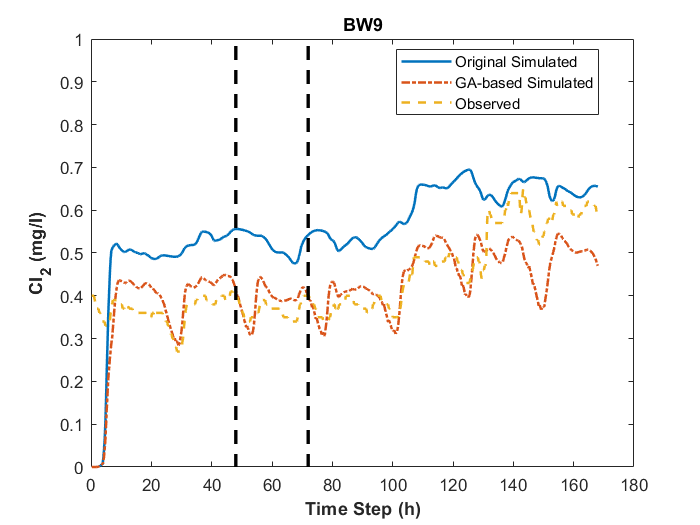

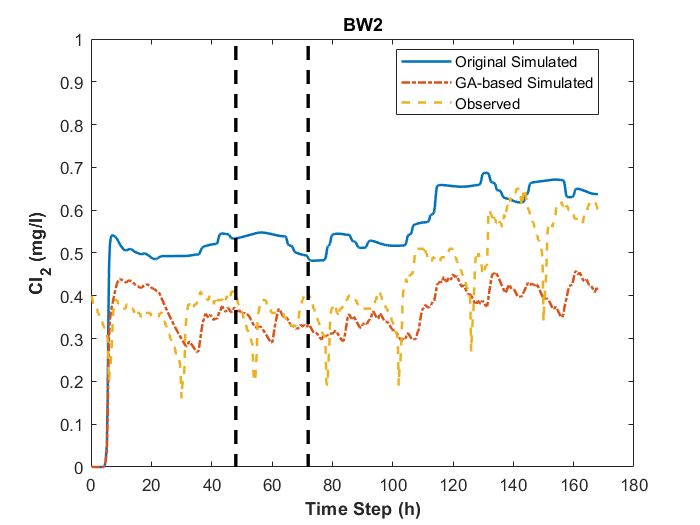

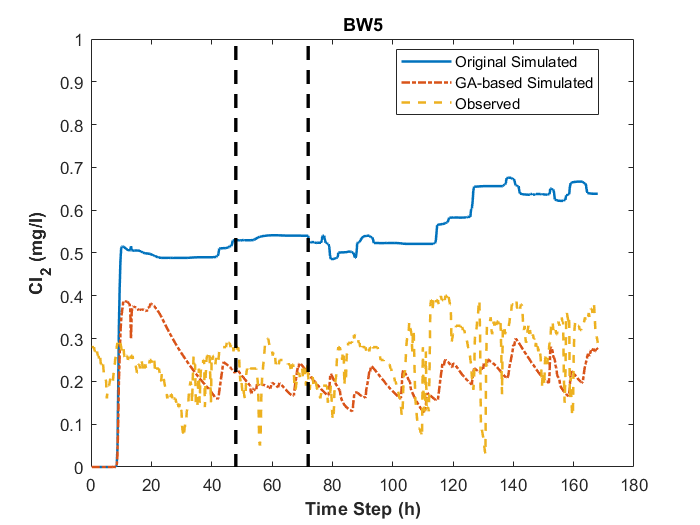

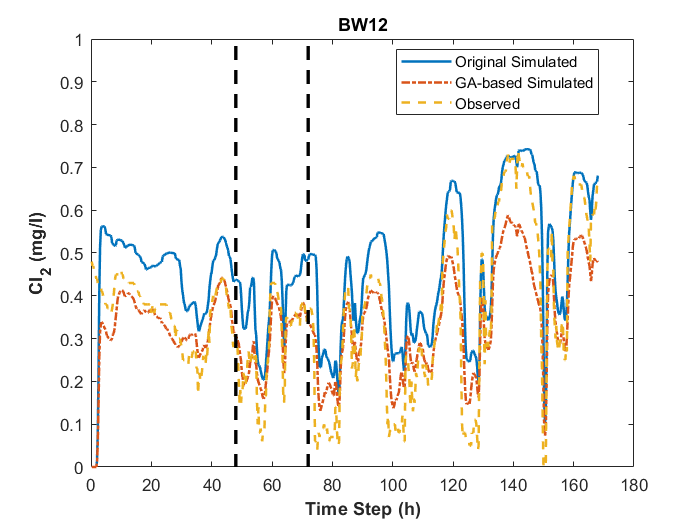


% figures for simulated and observed data

for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_D(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end

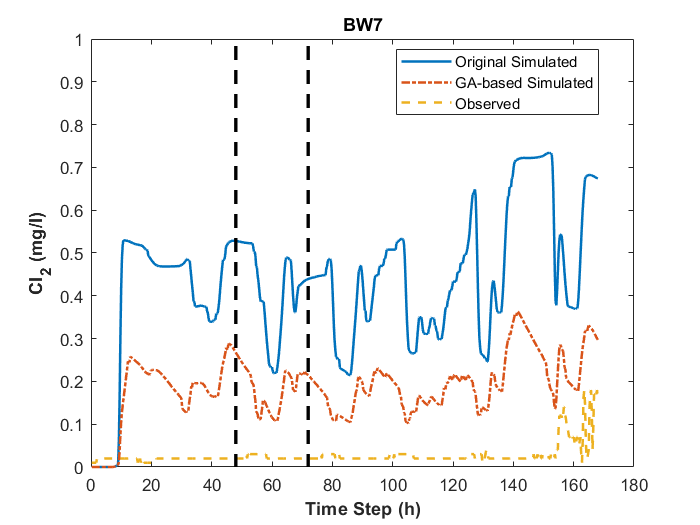

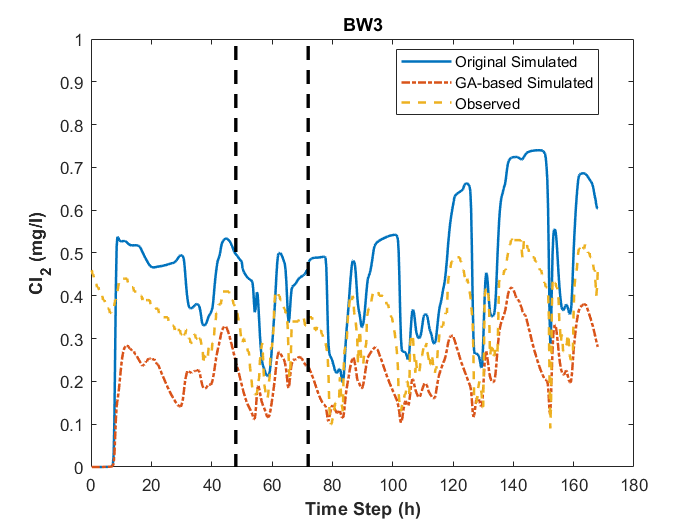

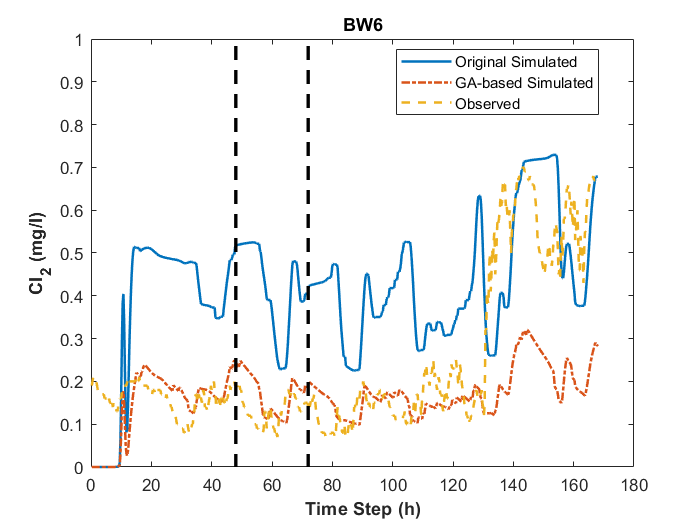


% figures for simulated and observed data (hydrants)
for i = 1:size(c_nodes_HydrantObs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_HydrantSim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_Hydrant_D(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_HydrantObs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Hydrant_Name{i})
end

### Roughness based Group Genetic Algorithm Implementation

Implement genetic algoritnm to solve the parameter optimization problem based on roughness groups.

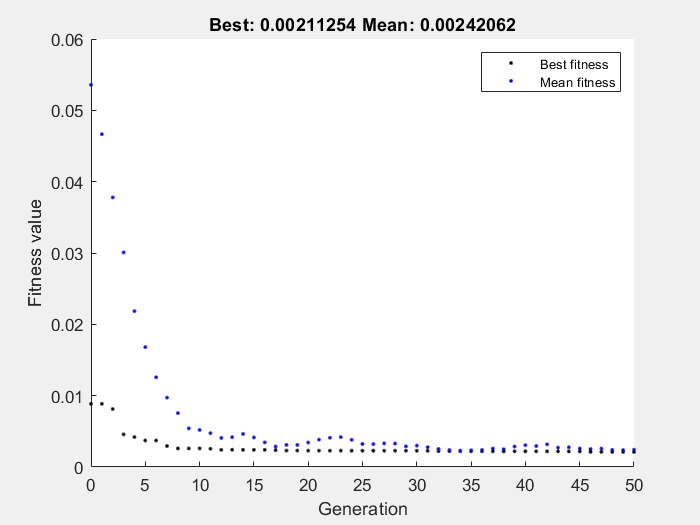

% genetic algorithm implementation
rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = -10*ones(11,1);
ub = 0*ones(11,1);

tic;
Mse_function = @(x) Mse_R(x,Obs_train,Junction_SelectIdx,R);
[x_R, fval_R] = ga(Mse_function,11,[],[],[],[],lb,ub,[],options);


t_R = toc;
fprintf('The computation time is %.2fs',t_R);

The computation time is 679.54s

% Test the ga result
theta_R = ones(2281,1); % units of m/day
for i = 1:2281
    if abs(R(i) - 0) <= 0.01
        theta_R(i) = x_R(1);
    elseif abs(R(i) - 0.1000) <= 0.01
        theta_R(i) = x_R(2);
    elseif abs(R(i) - 0.1399) <= 0.01
        theta_R(i) = x_R(3);
    elseif abs(R(i) - 1.5267) <= 0.01
        theta_R(i) = x_R(4);
    elseif abs(R(i) - 2.1576) <= 0.01
        theta_R(i) = x_R(5); 
    elseif abs(R(i) - 9.0114) <= 0.01
        theta_R(i) = x_R(6); 
    elseif abs(R(i) - 10.3677) <= 0.01
        theta_R(i) = x_R(7); 
    elseif abs(R(i) - 11.6809) <= 0.01
        theta_R(i) = x_R(8); 
    elseif abs(R(i) - 14.8687) <= 0.01
        theta_R(i) = x_R(9); 
    elseif abs(R(i) - 16.2377) <= 0.01
        theta_R(i) = x_R(10); 
    else
        theta_R(i) = x_R(11);
    end
end

net.setLinkWallReactionCoeff(1:np, theta_R);
net.setOptionsPipeWallReactionOrder(1);
quality_res_R = net.getComputedQualityTimeSeries;
c_nodes_R = quality_res_R.NodeQuality';
c_nodes_Sim_R = c_nodes_R(Junction_SelectIdx,1:end-1);
c_nodes_Sim_Hydrant_R = c_nodes_R(Junction_HydrantIdx,1:end-1);

Sim_R_val = c_nodes_Sim_R(:,3*96+1:end);
mse_after_R = mse_function(Sim_R_val,Obs_val);
fprintf('The train mse before calibration is %.4f, after calibration it is %.4f',mse_before_train,fval_R);

The train mse before calibration is 0.0430, after calibration it is 0.0021

fprintf('The train mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_R);

The train mse before calibration is 0.0396, after calibration it is 0.0092

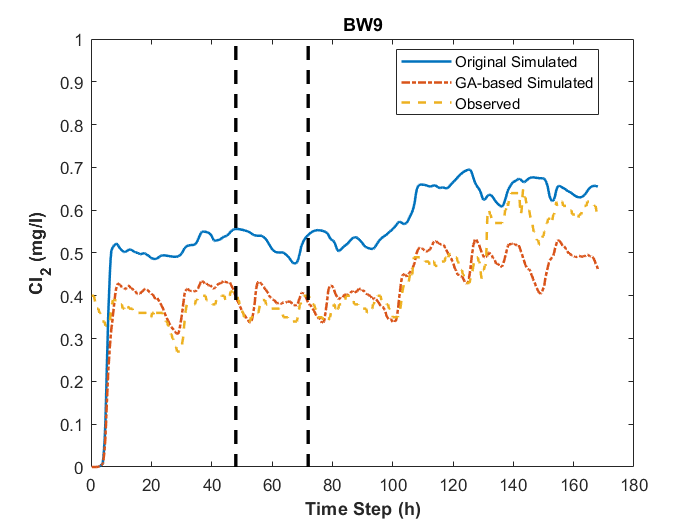

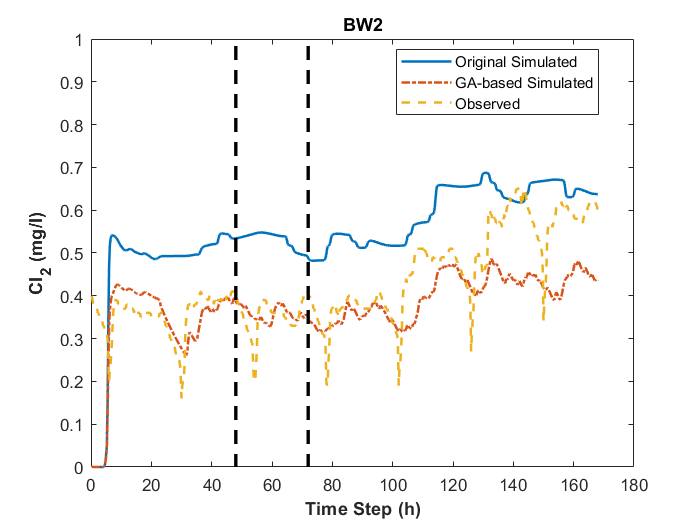

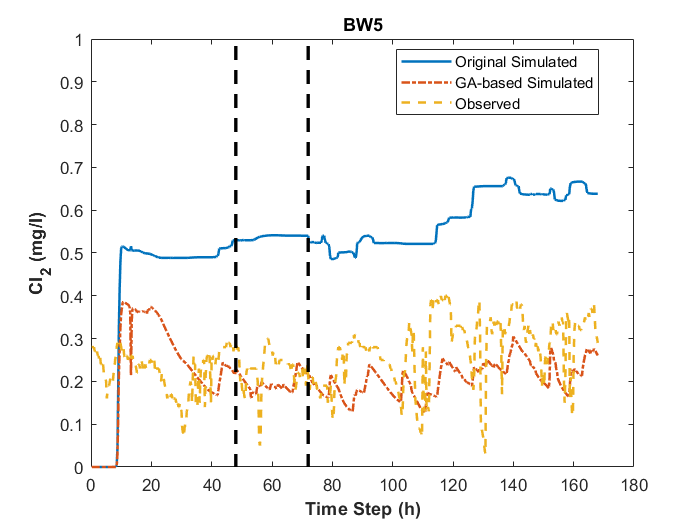

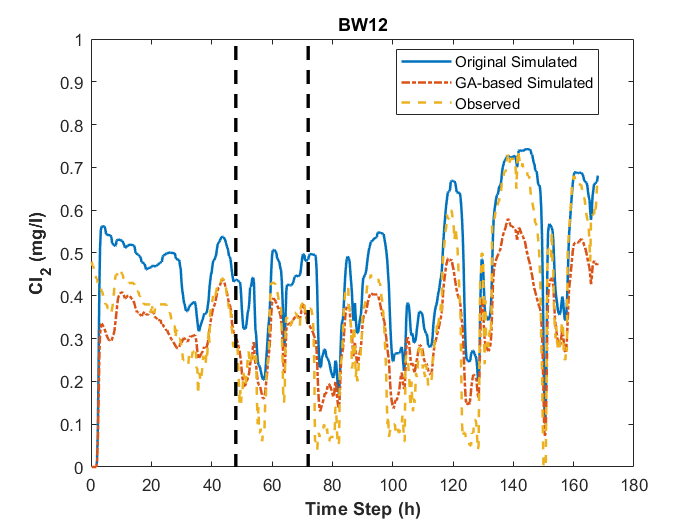


% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_R(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end

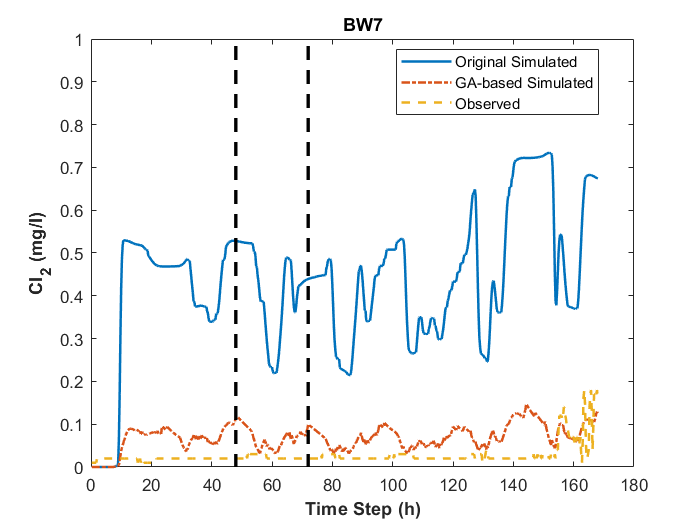

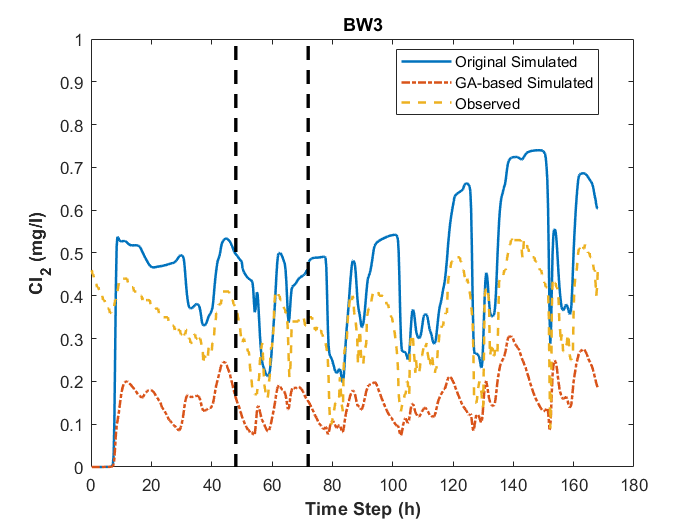

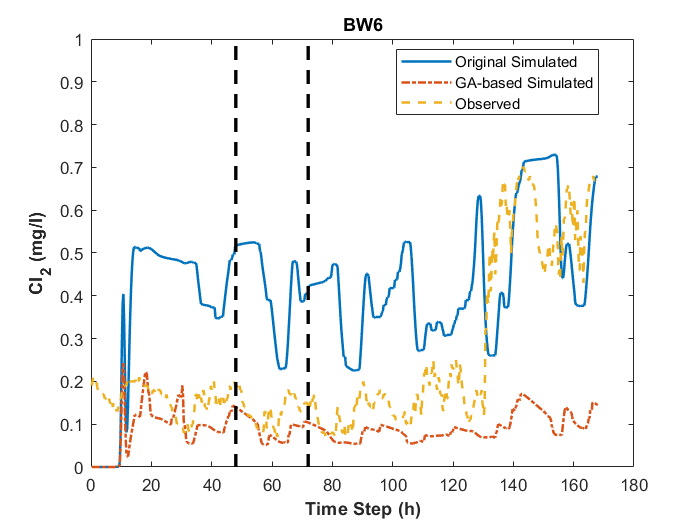


% figures for simulated and observed data (hydrants)
for i = 1:size(c_nodes_HydrantObs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_HydrantSim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_Hydrant_R(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_HydrantObs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Hydrant_Name{i})
end

### Roughness and Diameter based Group Genetic Algorithm Implementation

Implement genetic algoritnm to solve the parameter optimization problem based on roughness and diameter groups, in this we consider the roughness groups and diameter groups affect the bulk decay together.

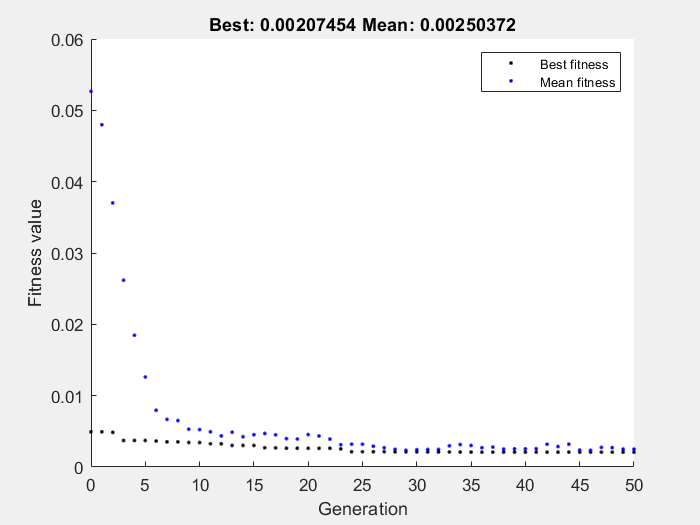

% genetic algorithm implementation
rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = -10*ones(22,1);
ub = 0*ones(22,1);

tic;
Mse_function = @(x) Mse_DandR(x,Obs_train,Junction_SelectIdx,D,R);
[x_DandR, fval_DandR] = ga(Mse_function,22,[],[],[],[],lb,ub,[],options);


t_DandR = toc;
fprintf('The computation time is %.2fs',t_DandR);

The computation time is 652.60s


% Test the ga result
thetaDandR = ones(2281,1); % units of m/day
for i = 1:2281
    if abs(R(i) - 0) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(1);
        else
            thetaDandR(i) = x_DandR(2);
        end
    elseif abs(R(i) - 0.1000) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(3);
        else
            thetaDandR(i) = x_DandR(4);
        end
    elseif abs(R(i) - 0.1399) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(5);
        else
            thetaDandR(i) = x_DandR(6);
        end
    elseif abs(R(i) - 1.5267) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(7);
        else
            thetaDandR(i) = x_DandR(8);
        end
    elseif abs(R(i) - 2.1576) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(9);
        else
            thetaDandR(i) = x_DandR(10);
        end
    elseif abs(R(i) - 9.0114) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(11);
        else
            thetaDandR(i) = x_DandR(12);
        end
    elseif abs(R(i) - 10.3677) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(13);
        else
            thetaDandR(i) = x_DandR(14);
        end
    elseif abs(R(i) - 11.6809) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(15);
        else
            thetaDandR(i) = x_DandR(16);
        end
    elseif abs(R(i) - 14.8687) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(17);
        else
            thetaDandR(i) = x_DandR(18);
        end 
    elseif abs(R(i) - 16.2377) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(19);
        else
            thetaDandR(i) = x_DandR(20);
        end
    else
        if D(i) <= 150
            thetaDandR(i) = x_DandR(21);
        else
            thetaDandR(i) = x_DandR(22);
        end
    end
end

net.setLinkWallReactionCoeff(1:np, thetaDandR);
net.setOptionsPipeWallReactionOrder(1);

quality_res_DandR = net.getComputedQualityTimeSeries;
c_nodes_DandR = quality_res_DandR.NodeQuality';
c_nodes_Sim_DandR = c_nodes_DandR(Junction_SelectIdx,1:end-1);
c_nodes_Sim_Hydrant_DandR = c_nodes_DandR(Junction_HydrantIdx,1:end-1);

Sim_DandR_val = c_nodes_Sim_DandR(:,3*96+1:end);
mse_after_DandR = mse_function(Sim_DandR_val,Obs_val);
fprintf('The train mse before calibration is %.4f, after calibration it is %.4f',mse_before_train,fval_DandR);

The train mse before calibration is 0.0430, after calibration it is 0.0021

fprintf('The validation mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_DandR);

The validation mse before calibration is 0.0396, after calibration it is 0.0101

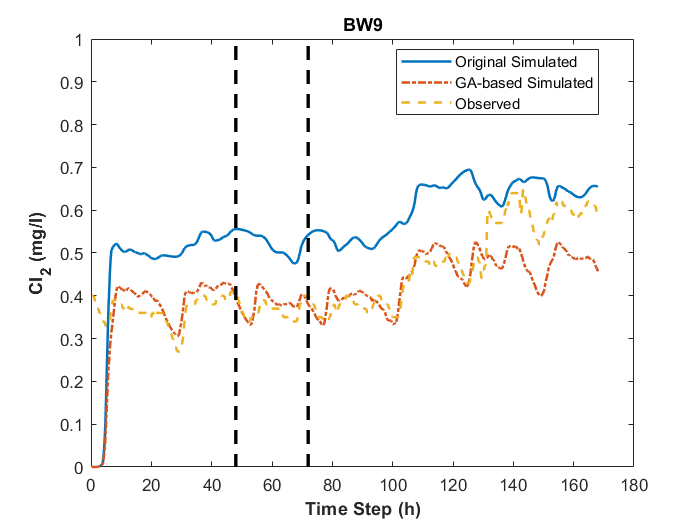

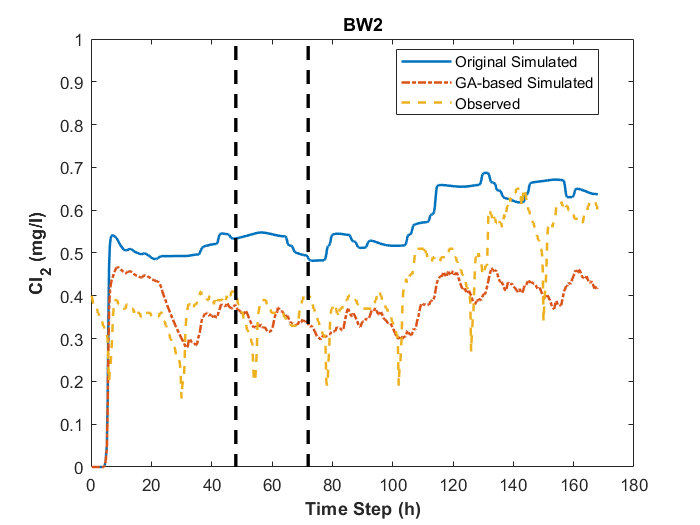

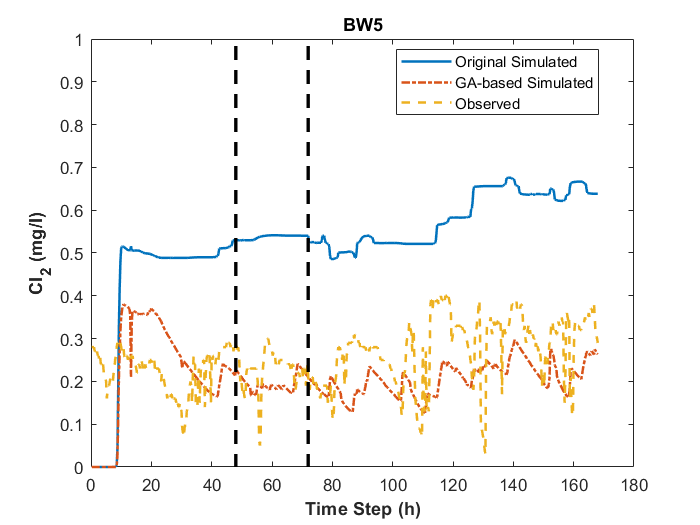

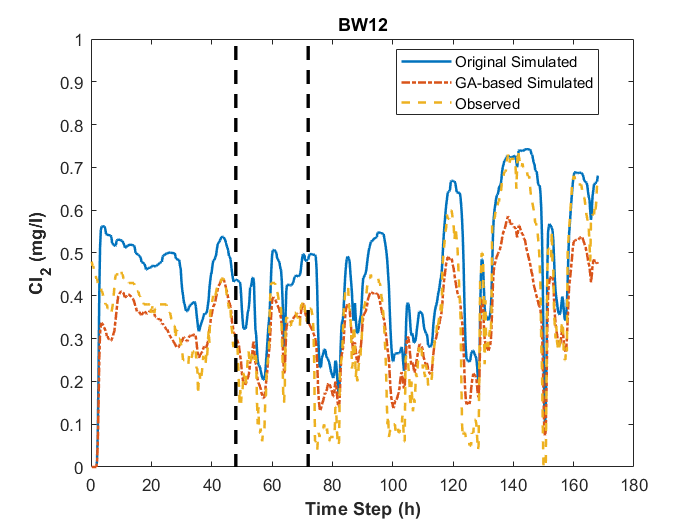


% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_DandR(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end

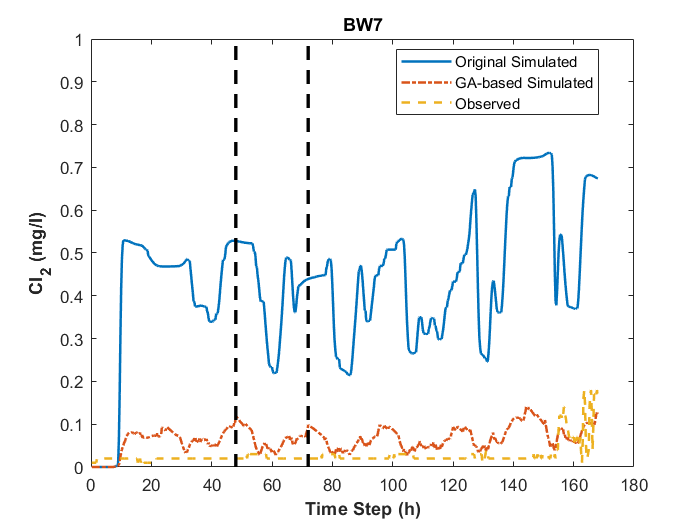

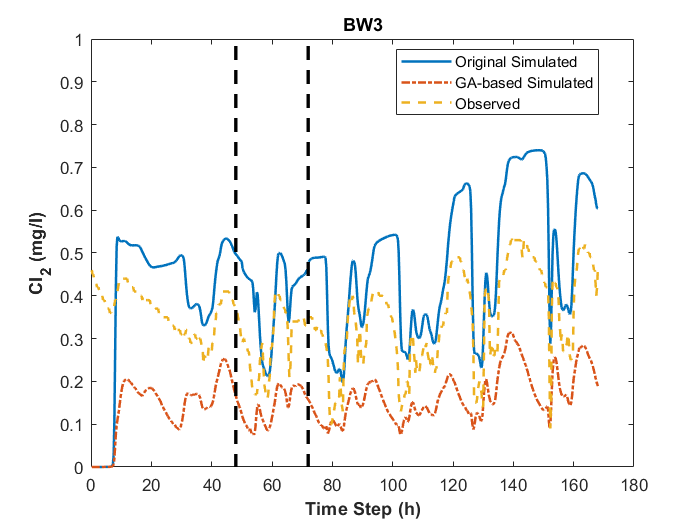

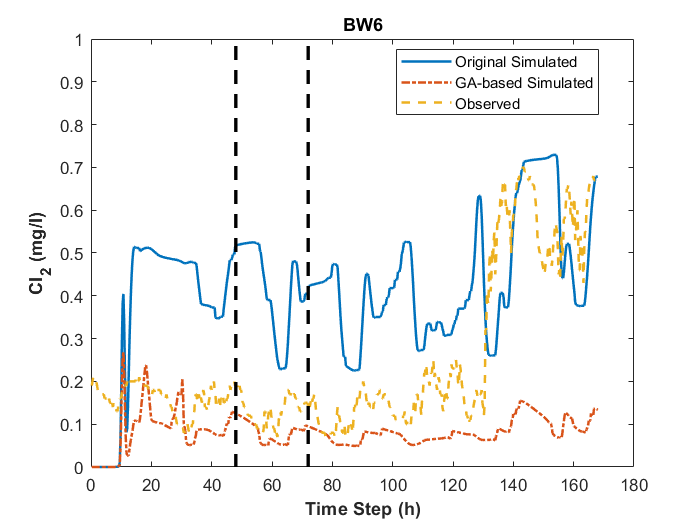


% figures for simulated and observed data (hydrants)
for i = 1:size(c_nodes_HydrantObs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_HydrantSim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_Hydrant_DandR(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_HydrantObs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Original Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Hydrant_Name{i})
end

fprintf('The single group k_w value is %.4f.',x_NoGroup);

The single group k_w value is -0.0083.

fprintf('The D-based group k_w value is %.4f, %.4f, %.4f, %.4f.',x_D);

The D-based group k_w value is -9.8449, 0.0000, -0.0998, -0.5156.

fprintf(['The R-based group k_w value is %.4f, %.4f, %.4f, %.4f, %.4f,\n %.4f, %.4f' ...
    ', %.4f, %.4f, %.4f, %.4f.'],x_R);

The R-based group k_w value is -4.9382, -0.0010, -0.0053, -0.6533, 0.0000,
 -1.3165, -0.5914, -0.1250, 0.0000, 0.0000, -1.9507.

fprintf(['The DR-based group k_w value is %.4f, %.4f, %.4f, %.4f, %.4f, %.4f, %.4f\n' ...
    ', %.4f, %.4f, %.4f, %.4f, %.4f, %.4f, %.4f, %.4f\n' ...
    ', %.4f, %.4f, %.4f, %.4f, %.4f, %.4f, %.4f, %.4f.'],x_DandR);

The DR-based group k_w value is -0.5000, -0.8281, -0.0088, -0.0664, 0.0000, -0.0577, -1.6836
, -0.1250, 0.0000, 0.0000, -4.3970, -1.5000, 0.0000, -0.5631, -0.2500
, -0.2050, -0.1241, -0.5000, 0.0000, 0.0000, -0.9648, -1.2075, 

### Test the hydrants

Find out the regulations in the node with hydrants.

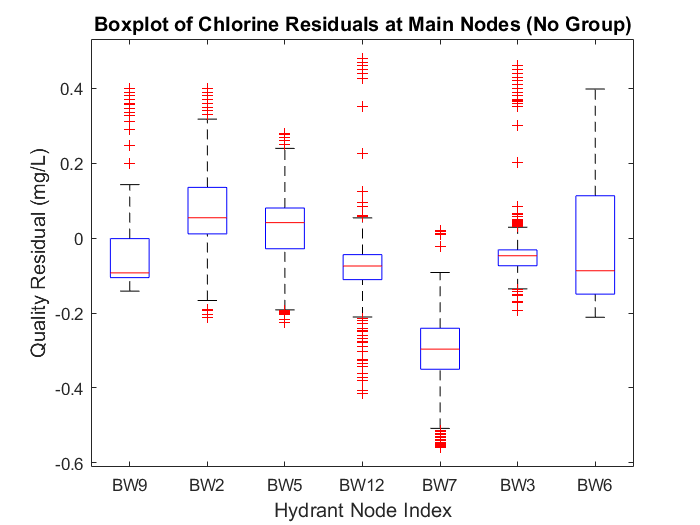

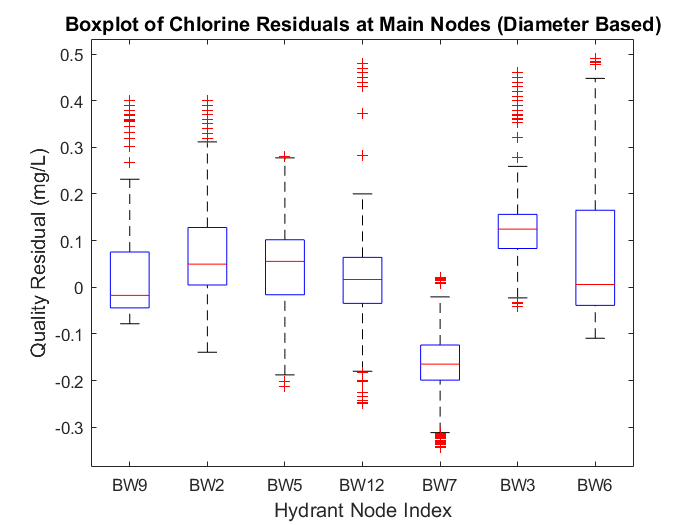

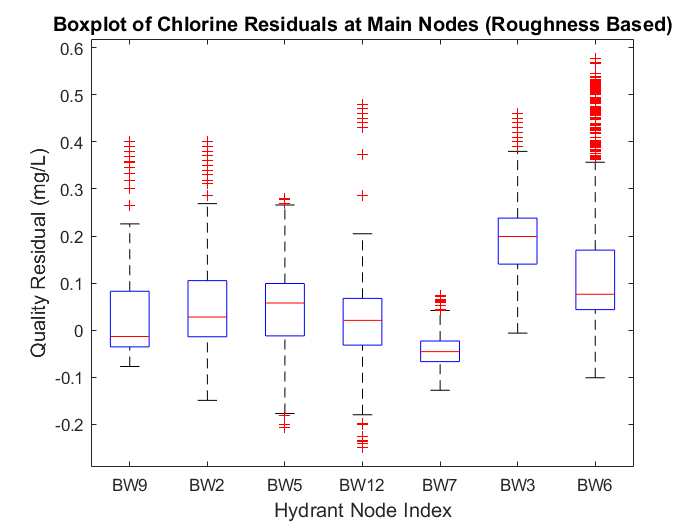

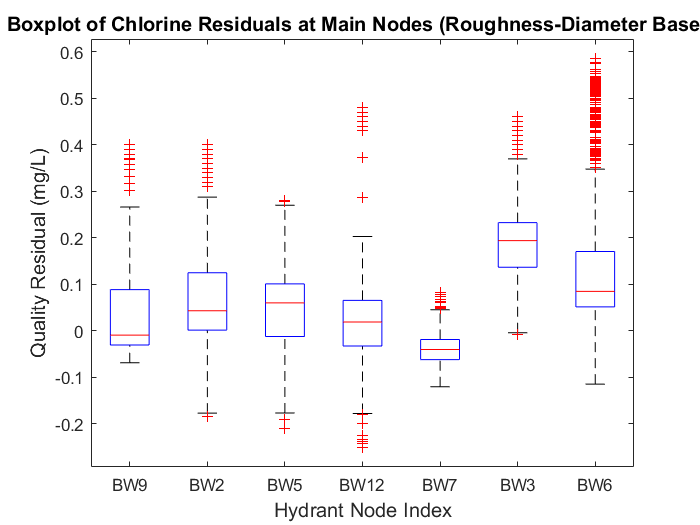

% % Boxplot to see the residual
% c_nodes_hydrant_Residual = c_nodes_hydrantObs - c_nodes_hydrantSim;
% c_nodes_hydrant_Residual = c_nodes_hydrant_Residual';

% Calculate the residuals at BW nodes.
c_nodes_NoGroup_Residual = [c_nodes_Obs;c_nodes_HydrantObs] - c_nodes_NoGroup([Junction_SelectIdx,Junction_HydrantIdx],1:end-1);
c_nodes_NoGroup_Residual = c_nodes_NoGroup_Residual';

c_nodes_D_Residual = [c_nodes_Obs;c_nodes_HydrantObs] - c_nodes_D([Junction_SelectIdx,Junction_HydrantIdx],1:end-1);
c_nodes_D_Residual = c_nodes_D_Residual';

c_nodes_R_Residual = [c_nodes_Obs;c_nodes_HydrantObs] - c_nodes_R([Junction_SelectIdx,Junction_HydrantIdx],1:end-1);
c_nodes_R_Residual = c_nodes_R_Residual';

c_nodes_DandR_Residual = [c_nodes_Obs;c_nodes_HydrantObs] - c_nodes_DandR([Junction_SelectIdx,Junction_HydrantIdx],1:end-1);
c_nodes_DandR_Residual = c_nodes_DandR_Residual';

c_nodes_Residual = {c_nodes_NoGroup_Residual,c_nodes_D_Residual,c_nodes_R_Residual,...
    c_nodes_DandR_Residual};
Residual_Name = {'(No Group)','(Diameter Based)','(Roughness Based)','(Roughness-Diameter Based)'};

for i = 1:length(c_nodes_Residual)
    figure,
    boxplot(c_nodes_Residual{i});
    xlabel('Hydrant Node Index','FontSize',12)
    ylabel('Quality Residual (mg/L)','FontSize',12)
    title(['Boxplot of Chlorine Residuals at Main Nodes ',Residual_Name{i}],'FontSize',12)
    xticklabels([Junction_Name,Junction_Hydrant_Name]);
end